### GET DATA

Read the data and transform to matrix.

data = readtable("benzene.dat");
data = table2array(data(:, 2:5)); % skip first line (string)

### CREATE A 2D MESHGRID FOR PLOTTING

Find min and max coordinates for grid bounds

x_min = min(data(:,1)); x_max = max(data(:,1));
y_min = min(data(:,2)); y_max = max(data(:,2));

Define a vector for grid

X = x_min - 1 : 0.02 : x_max + 1;
Y = y_min - 1 : 0.02 : y_max + 1;

Make meshgrid

[x_grid, y_grid] = meshgrid(X, Y);

### VARIABLES

Sum of all potentials

V = zeros(size(x_grid));

Electrostatic constant

K = 1 / (4 * pi * 8.85e-12);

Particle radius

r = 0.1;

### CALCULATE POTENTIALS

Get potential for every particle (10 rows = 10 parcticles). `calculate_potential_3D` returns potential of charge

for i = 1 : size(data,1)
    V = V + calculate_potential_2D(x_grid, y_grid, data(i,1), data(i,2), data(i,4), K, r);
end

### PLOT

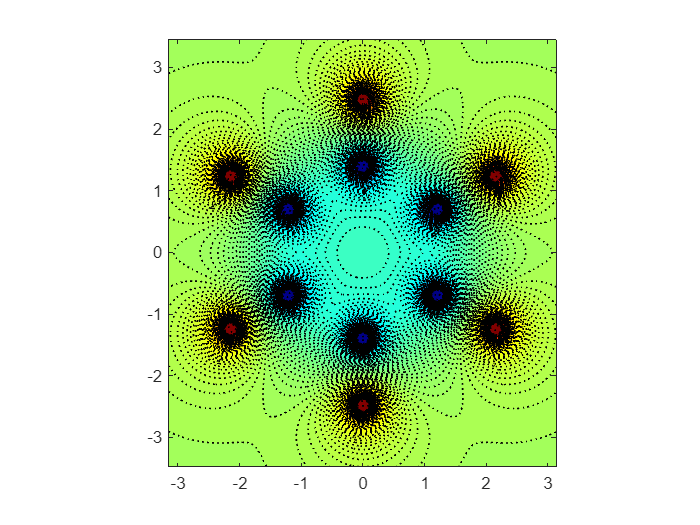

figure
contourf(x_grid, y_grid, V, 200, ':', 'LineWidth', 1)
colormap(jet)
ax=gca;
axis(ax,'equal')

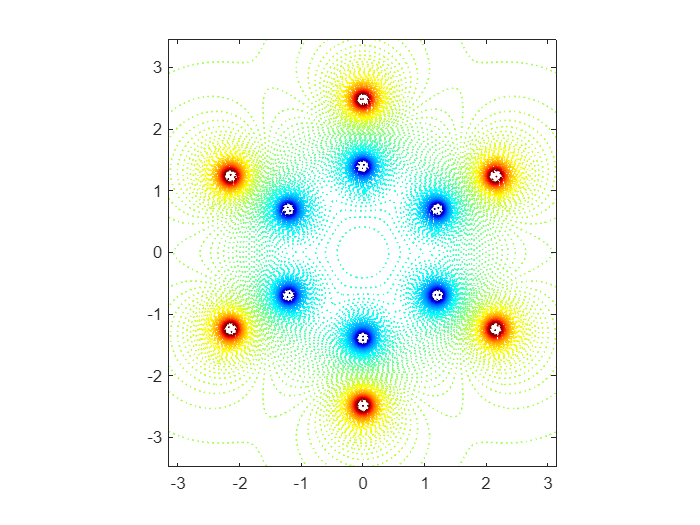

figure
contour(x_grid, y_grid, V, 200, ':', 'LineWidth', 1)
colormap(jet)
ax=gca;
axis(ax,'equal')

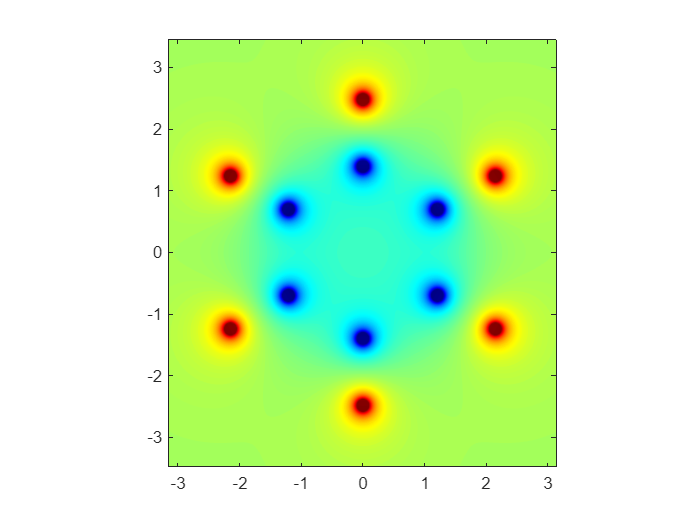

figure
contourf(x_grid, y_grid, V, 200, 'LineStyle', 'none')
colormap(jet)
ax=gca;
axis(ax,'equal')

### CREATE A 2D MESHGRID FOR PLOTTING

Find min and max coordinates for grid bounds

minC = min([min(data(:,1)), min(data(:,2)), min(data(:,3))]);
maxC = max([max(data(:,1)), max(data(:,2)), max(data(:,3))]);
distMinMax = maxC - minC;

Make meshgrid.

[x_grid, y_grid, z_grid] = meshgrid(minC*1.3 : 0.02 : maxC*1.3);

Initialize array to store potentials of particles.

V = zeros(size(x_grid));

### CALCULATE POTENTIALS

for i = 1 : size(data, 1)
    V = V + calculate_potential_3D(x_grid, y_grid, z_grid, data(i,1), data(i,2), data(i,3), data(i,4));
end

### PLOT

Draw all 3 layers.

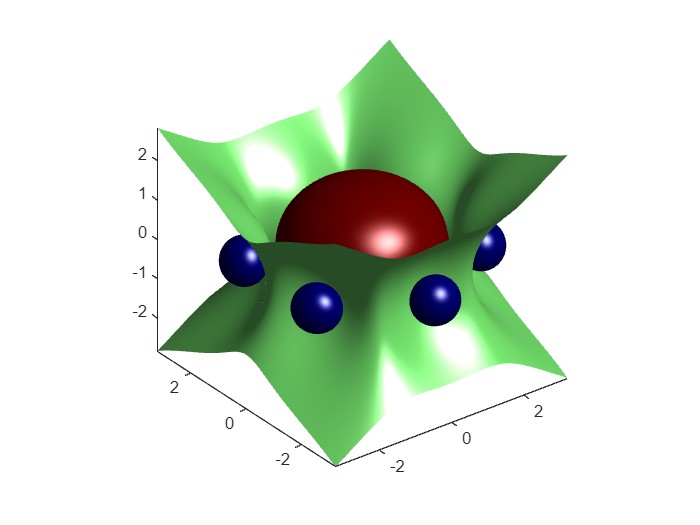

figure
isosurface(x_grid, y_grid, z_grid, V, 0)
colormap(jet)
hold on 
isosurface(x_grid, y_grid, z_grid, V, 1.0e-10)
isosurface(x_grid, y_grid, z_grid, V, -1.0e-10)
ax=gca;
axis(ax,'equal')